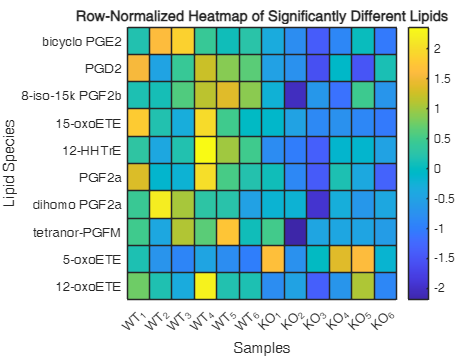

%% Statistical Analysis for Lipid Data (WT vs KO)
% This script analyzes lipid data, selecting the appropriate statistical
%test (parametric or nonparametric) based on data normality and variance.

% Load the dataset
filename = 'LipidMapsInvData.xlsx';
sheet = 'LipidMapsSD data';
data = readtable(filename, 'Sheet', sheet);

% Extract lipid species names and group data
lipids = data{:, 1}; % First column: lipid names
WT_data = data{:, 2:7}; % WT columns (Wt_1 to Wt_6)
KO_data = data{:, 8:13}; % KO columns (KO_1 to KO_6)

% Initialize results table
results = table(lipids, cell(size(lipids)), NaN(size(lipids)), ...
    NaN(size(lipids)), NaN(size(lipids)), cell(size(lipids)), NaN(size(lipids)), ...
    NaN(size(lipids)), NaN(size(lipids)), 'VariableNames', ...
    {'Lipid', 'TestType', 'PValue', 'NormalityWT', 'NormalityKO', 'ComparisonUsed', 'WT_Mean', 'KO_Mean', 'FoldChange'});

% Loop through each lipid species
for i = 1:length(lipids)
    wt = WT_data(i, :); % WT replicates for this lipid
    ko = KO_data(i, :); % KO replicates for this lipid

    % Remove NaN values
    wt = wt(~isnan(wt));
    ko = ko(~isnan(ko));

    % Calculate means and fold change
    wt_mean = mean(wt);
    ko_mean = mean(ko);
    fold_change = ko_mean / wt_mean;

    % Test normality using Shapiro-Wilk test
    [h_wt, p_wt] = swtest(wt); % WT group
    [h_ko, p_ko] = swtest(ko); % KO group

    % Store normality results
    results.NormalityWT(i) = p_wt; % p-value for WT normality
    results.NormalityKO(i) = p_ko; % p-value for KO normality

    % Determine test type (normality + variance equality)
    if p_wt > 0.05 && p_ko > 0.05 % Both groups are normal
        % Test for equal variances
        [h_var, ~] = vartest2(wt, ko);
        if h_var == 0 % Equal variances
            test_type = 't-test';
            [~, p] = ttest2(wt, ko, 'Vartype', 'equal');
            comparison_used = 'Parametric (Equal Variance)';
        else % Unequal variances
            test_type = 'Welch''s t-test';
            [~, p] = ttest2(wt, ko, 'Vartype', 'unequal');
            comparison_used = 'Parametric (Unequal Variance)';
        end
    else % Non-normal data
        test_type = 'Mann-Whitney U';
        p = ranksum(wt, ko);
        comparison_used = 'Nonparametric';
    end

    % Store results
    results.TestType{i} = test_type; % Assign to cell array
    results.PValue(i) = p;
    results.ComparisonUsed{i} = comparison_used; % Store comparison used
    results.WT_Mean(i) = wt_mean; % Store WT mean
    results.KO_Mean(i) = ko_mean; % Store KO mean
    results.FoldChange(i) = fold_change; % Store fold change
end

% Filter significantly different lipids
significant_results = results(results.PValue < 0.05, :);

% Create a row-normalized heatmap for significantly different lipids
if ~isempty(significant_results)
    % Extract concentration data for heatmap
    significant_indices = find(results.PValue < 0.05);
    heatmap_data = [WT_data(significant_indices, :) KO_data(significant_indices, :)];
    heatmap_data = normalize(heatmap_data, 2); % Row-normalize

    % Generate heatmap
    figure;
    heatmap_labels = ["WT_1", "WT_2", "WT_3", "WT_4", "WT_5", "WT_6", ...
                      "KO_1", "KO_2", "KO_3", "KO_4", "KO_5", "KO_6"];
    heatmap(heatmap_labels, significant_results.Lipid, heatmap_data, ...
            'Colormap', parula, 'ColorbarVisible', 'on');
    title('Row-Normalized Heatmap of Significantly Different Lipids');
    xlabel('Samples');
    ylabel('Lipid Species');
end


% Save results to a new Excel file
output_filename = 'LipidStatsResults.xlsx';
writetable(results, output_filename);

% Display completion message
fprintf('Statistical analysis complete. Results saved to %s.\n', output_filename);

Statistical analysis complete. Results saved to LipidStatsResults.xlsx.
